load train_1.mat

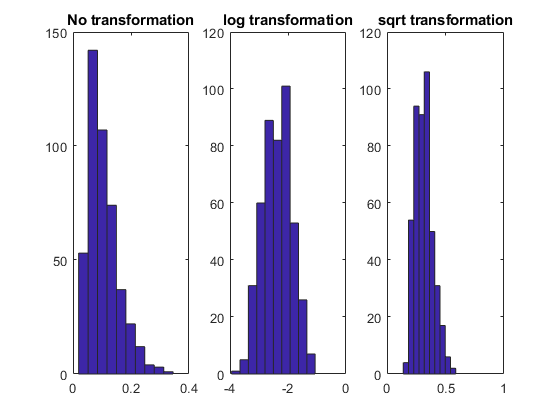

figure; 
subplot(131); hist(train(:, 6)); title('No transformation');
subplot(132); hist(log(train(:, 6)));title('log transformation');
subplot(133); hist(sqrt(train(:, 6))); title('sqrt transformation');

The non-transformed data looks t-distributed. I think the log transformation may be best for proceeding. log+1 transformation! autoscale.

trans_train = log(train+1);

1 was added to every data point to prevent a negative infinity result when log transforming.

I ran the cell below to double check there are no negative infinity values.

sum(trans_train(:, 7) == -Inf)

ans = 0

Data should be autoscaled. (x-mean/Std)

[aTrain, mTrain, stdTrain] = auto(trans_train);

Now turn the matrix back into a table so I can upload it to github and others can use it.

Norm_data = array2table(aTrain);
filename = 'normalized_data.xlsx';
writetable(Norm_data, filename, 'sheet', 2, 'Range', 'D1')